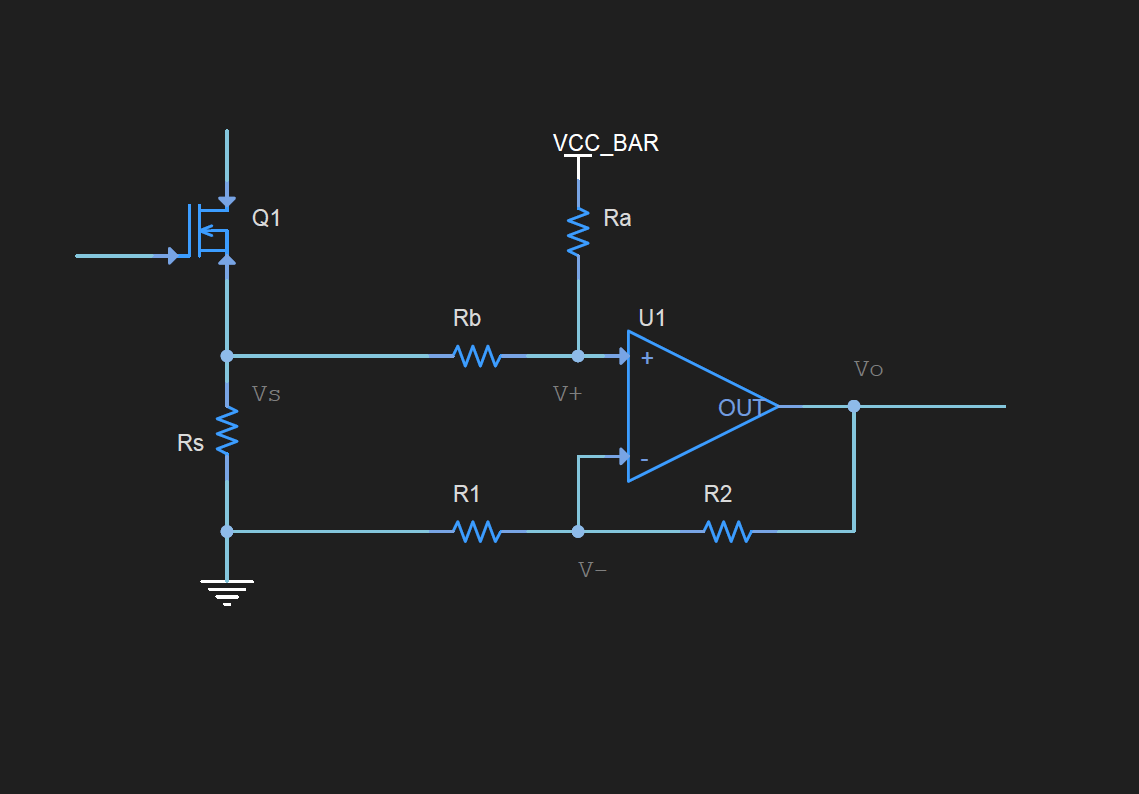

ra = 54000;
rb = 5400;
r1 = 5400;
r2 = 16200;
vcc = 3.3;
kv2d = 65535/vcc;
rs = 0.005;
syms Ra Rb R1 R2 Vcc Vo Vi Vam Rs 
f1 = (Vcc-Vam)/Ra == (Vam-Vi)/Rb;
f2 = (Vo-Vam)/R2 == Vam/R1;
vam = solve(f1, Vam);
vo = collect(simplify(solve(subs(f2, Vam, vam),Vo)), [Vi, Vcc])

$$vo = \frac{\mathrm{Ra}\,\left(R_{1}+R_{2}\right)}{R_{1}\,\left(\mathrm{Ra}+\mathrm{Rb}\right)}\,\mathrm{Vi}+\frac{\mathrm{Rb}\,\left(R_{1}+R_{2}\right)}{R_{1}\,\left(\mathrm{Ra}+\mathrm{Rb}\right)}\,\mathrm{Vcc}$$



vor = subs(vo, [Ra, Rb, R1, R2, Vcc], [ra, rb, r1, r2, vcc])

$$vor = \frac{40\,\mathrm{Vi}}{11}+\frac{6}{5}$$

coef = coeffs(vor)

$$coef = \left(\begin{array}{cc} \frac{6}{5} & \frac{40}{11} \end{array}\right)$$

bias = double(coef(1))

bias = 1.2000

gain = double(coef(2))

gain = 3.6364


syms data v2d
f3 = data == vo*v2d

$$f3 = \mathrm{data}=\mathrm{v2d}\,\left(\frac{\mathrm{Ra}\,\left(R_{1}+R_{2}\right)}{R_{1}\,\left(\mathrm{Ra}+\mathrm{Rb}\right)}\,\mathrm{Vi}+\frac{\mathrm{Rb}\,\left(R_{1}+R_{2}\right)}{R_{1}\,\left(\mathrm{Ra}+\mathrm{Rb}\right)}\,\mathrm{Vcc}\right)$$

vi = collect(simplify(solve(f3, Vi)),[Vcc, data])

$$vi = \left(-\frac{\mathrm{Rb}}{\mathrm{Ra}}\right)\,\mathrm{Vcc}+\frac{R_{1}\,\left(\mathrm{Ra}+\mathrm{Rb}\right)}{\mathrm{Ra}\,\mathrm{v2d}\,\left(R_{1}+R_{2}\right)}\,\mathrm{data}$$

vir = subs(vi, [Ra, Rb, R1, R2, Vcc, v2d], [ra, rb, r1, r2, vcc, kv2d])

$$vir = \frac{47244640256\,\mathrm{data}}{3411765839313455}-\frac{33}{100}$$

is = vi/Rs

$$is = -\frac{-\left(-\frac{\mathrm{Rb}}{\mathrm{Ra}}\right)\,\mathrm{Vcc}-\frac{R_{1}\,\left(\mathrm{Ra}+\mathrm{Rb}\right)}{\mathrm{Ra}\,\mathrm{v2d}\,\left(R_{1}+R_{2}\right)}\,\mathrm{data}}{\mathrm{Rs}}$$

isr = subs(is, [Ra, Rb, R1, R2, Vcc, v2d, Rs], [ra, rb, r1, r2, vcc, kv2d, rs])

$$isr = \frac{1889785610240\,\mathrm{data}}{682353167862691}-66$$

coef = coeffs(isr)

$$coef = \left(\begin{array}{cc} -66 & \frac{1889785610240}{682353167862691} \end{array}\right)$$

bias = double(coef(1))

bias = -66

gain = double(1/coef(2))

gain = 361.0744